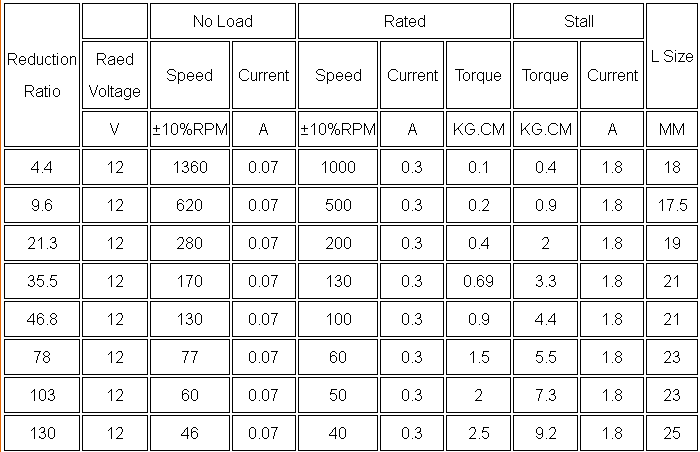

% Valores aproximados
m = 0.150;
L = 0.207;
g = 9.81;
Jeq = 0.0048;
r = 0.126;

VEL = 620;  % RPM
VELR = VEL*2*pi/60; % rad/s
STALL = 0.9; % Kg.Cm
TORQUE = STALL*9.82/10; % N.m
% Kt = Kt/Ra
kt = TORQUE/12

kt = 0.0737

Kv = 12/VELR

Kv = 0.1848

% constantes
a = (Jeq + m*r^2);
b = m*L*r;
c = (4*m*L^2)/3;
d = m*g*L;
e = (a*c - b^2);

% Matriz de estados
A = [0 1 0 0;
    0 -c*Kv*kt/e b*d/e 0;
    0 0 0 1;
    0 -b*Kv*kt/e d*a/e 0];
B = [0 ; c*kt/e; 0; b*kt/e];

C = [1 0 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1];

D = 0;

sys = ss(A,B,C,D);

% Custo por estado
Q = [100 0 0 0;
    0 1 0 0;
    0 0 10 0;
    0 0 0 1;];

% Custo de controle
R = 10;

K = lqr(sys,Q,R)

K =    -3.1623   -2.0469   48.6226    7.8371


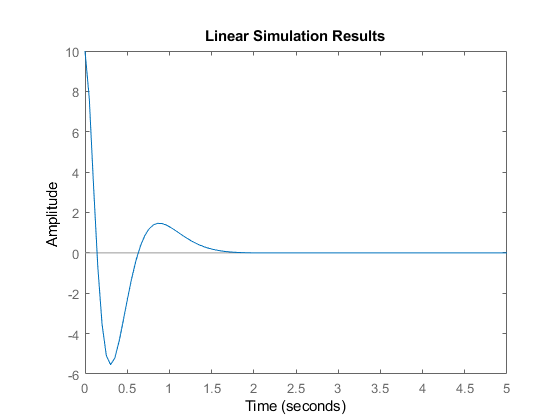

% Continuo
c = 180/pi;
% C = [c 0 0 0;
%     0 c 0 0;
%     0 0 c 0; 
%     0 0 0 c];
C = [0 0 c 0];
t = linspace(0,5);
sysmf = ss(A-B*K,B,C,D);
u = zeros(1,length(t));
xo = [0 0 10*pi/180 0];
lsim(sysmf,u,t,xo)

% Discreto
Ts = 1/100;
sysd = c2d(sys,Ts);
Kd = dlqr(sysd.A,sysd.B,Q,R)

Kd =    -2.8485   -1.8769   45.2991    7.2889


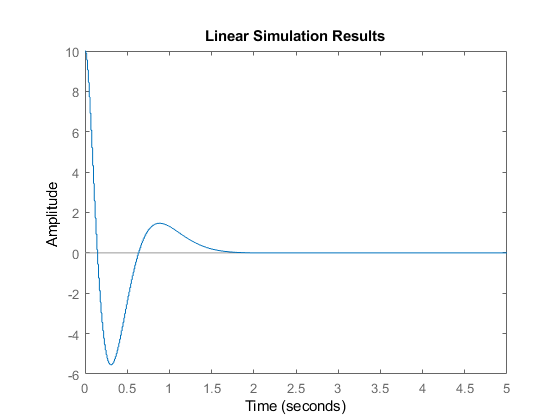

t = 0:Ts:5;
u = zeros(1,length(t));
% C = [c 0 0 0;
%     0 c 0 0;
%     0 0 c 0; 
%     0 0 0 c];
C = [0 0 c 0];
sysdmf = ss(sysd.A - sysd.B*Kd,sysd.B,C,D,Ts);
lsim(sysdmf,u,t,xo)